Before presenting the segmentation techniques we must introduce some relationships between pixels to define the connected components or regions of an image

# **Basic Relationships Between Pixels**

slide 737

**Neighbors of a pixel**

**4-neighbors**

**N4(p)**, are the four pixels located at (x+1, y), (x-1, y), (x, y+1), (x, y-1).

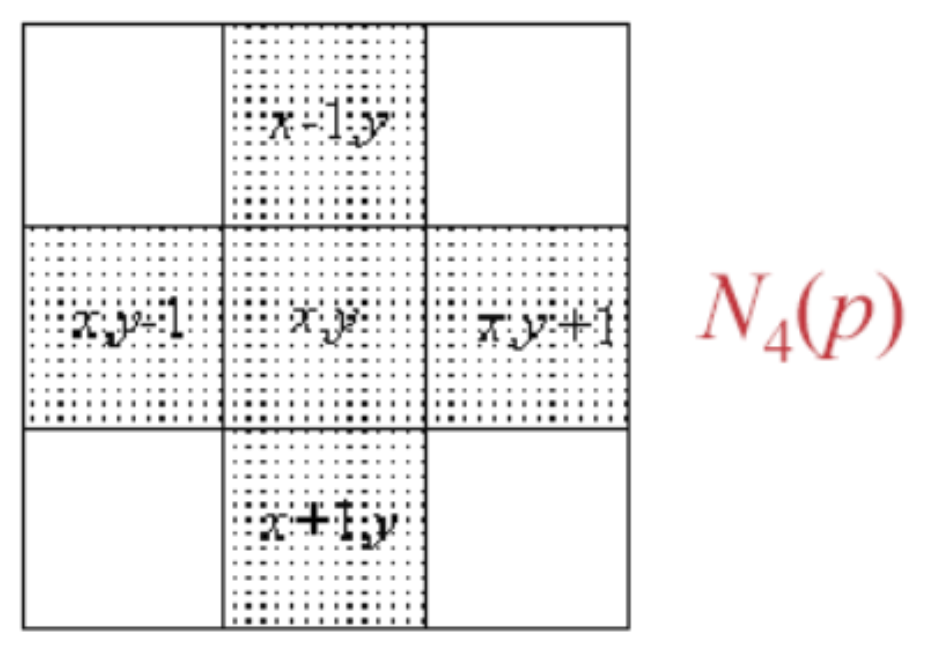

**ND(p)**  the four **diagonal neighbors** of p(x,y) are given by (x+1, y+1), (x+1, y-1), (x-1, y+1), (x-1 ,y-1)

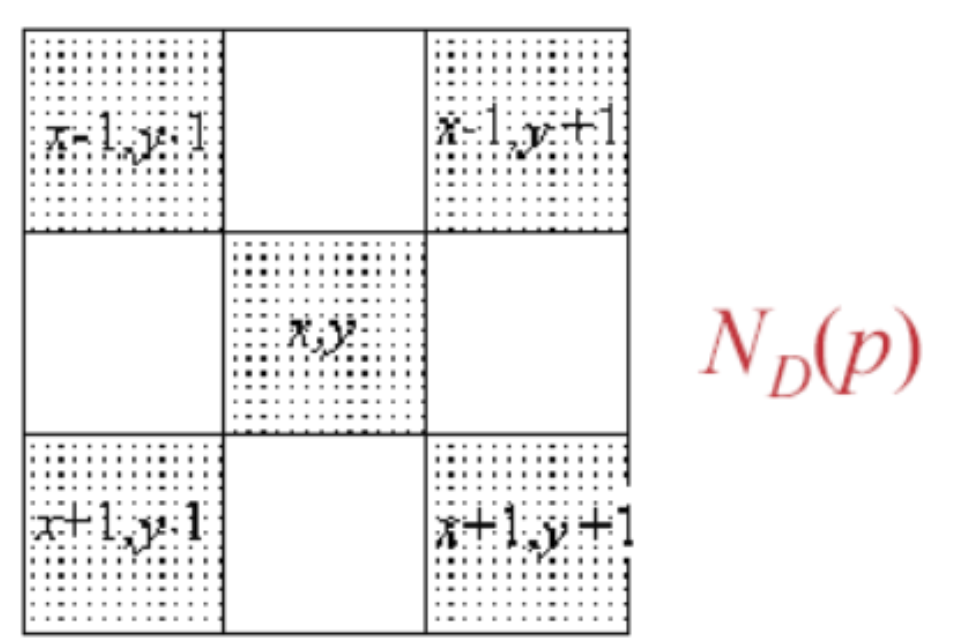

**8-neighbors**

The points ND(P) and N4(P) are together known as 8-neighbors of the point P, **denoted by N8(P)**.

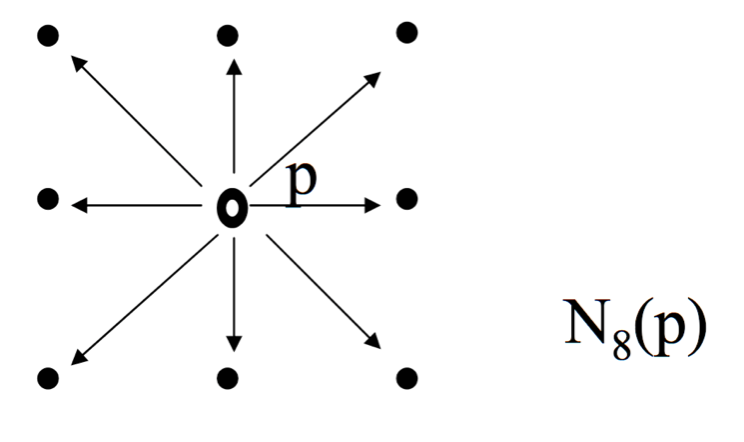

**Pixel connectivity: Adjacency**

**Two pixels are connected if they are neighbors and their gray levels satisfy some specified criterion of similarity.**

In a binary image two pixels are connected if they are 4-neighbors and have same value (0/1).

**In a gray level image, two neighboring pixels p and q are connected if their values belong to the same subset of similar gray levels.**

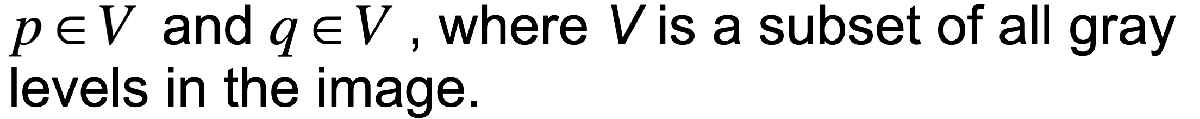

**adjacency:         (**slide 743)

**4-adjacency: **Two pixels p and q with values from V are 4- adjacent if q is in the set N4(p).

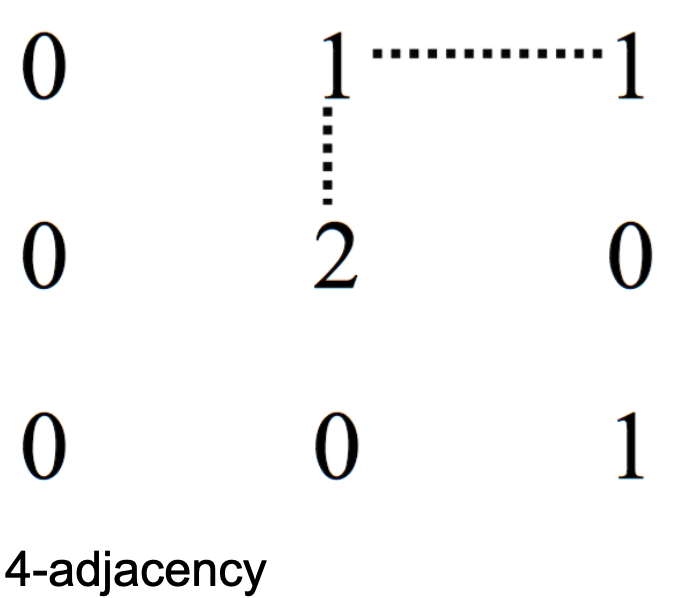

**8-adjacency: **Two pixels p and q with values from V are 8- adjacent if q is in the set N8(p).

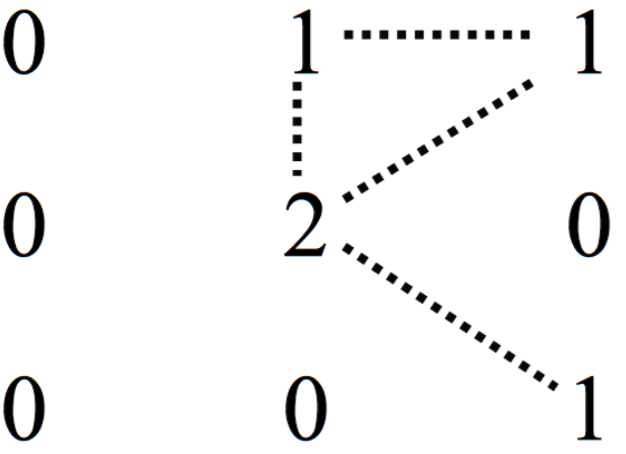

**Paths   (**slide 746)

A path from pixel p with coordinates (x, y) to pixel q with coordinates (s, t) is a sequence of distinct pixels with coordinates:

(x0, y0), (x1, y1), (x2, y2) ... (xn, yn), where (x0, y0)=(x, y) and (xn, yn)=(s, t);

(xi, yi) is adjacent to (xi-1, yi-1)   1≤ i ≤ n

n is the length of the path

**Connected Components    (**slide 747)

If p and q are pixels of an image subset S then **p is connected to q** in S if there is a path from p to q consisting entirely of pixels in S.

For every pixel p in S, the set of pixels in S that are connected to p is called a **connected component** of S.

If S has only one connected component then S is called 

**Connected Set (Region)**

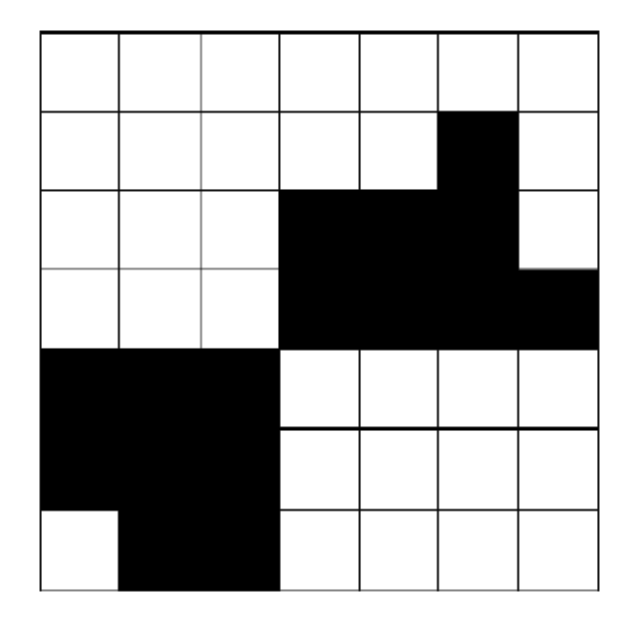

**two connected components** by  4-adjacency

**one connected component** by  8-adjacency

**MATLAB function:**

CC = **bwconncomp**(BW) returns the connected components CC found in the binary image BW. bwconncomp uses a default connectivity of 8 for two dimensions.

**example**: Find the number of connected components in a binary image, find and remove the biggest component 

clear
close all
BW = imread('text.png');
subplot(1,2,1)
imshow(BW)
title('input color image')
BW=rgb2gray(BW);
BWi=imbinarize(BW);
subplot(1,2,2)
imshow(BWi)
title('binary image')
BWb=imcomplement(BWi);
CC = bwconncomp(BWb)
% CC = struct with fields:
%     Connectivity: 8
%        ImageSize: [256 256]
%       NumObjects: 88
%     PixelIdxList: {1x88 cell}
CC = bwconncomp(BWb);
numPixels = cellfun(@numel,CC.PixelIdxList);
%A = cellfun(func,C) applies the function func to the 
%contents of each cell of cell array C
[biggest,idx] = max(numPixels);
t=['numero pixel max = ', num2str(biggest)];
disp(t)
% remove the biggest component
BWb(CC.PixelIdxList{idx}) = 0;
figure
imshowpair(BW,BWb,'montage')

**Exercise** :

Read a gray scale image, select by ginput function a gray level, input a delta value.

Compute the number of regions (gray level = input value + - delta), the number of pixel for each region and display:

the image of the regions

the input image without the largest region

clear
close all
x1=imread('moon.tif');
x=x1;
figure;
image(x);
axis image;
colormap(gray);
disp('select a pixel')
[X,Y]=ginput(1);
X=uint16(X)
Y=uint16(Y)
k=x(Y,X)
d=input('input delta ')
% set to 0 all the pixel (x<(k-d))|(x>(k+d))
x((x<(k-d))|(x>(k+d)))=0;
% set to 1 all the pixel in the regions
x(x~=0)=1;
% find the total number of pixels in the regions
a=find(x==1);
[xa,xb]=size(a);
t=['total pixel number = ', num2str(xa)];
disp(t)
CC = bwconncomp(x);
t=['number of regions = ', num2str(CC.NumObjects)];
disp(t)
figure
imshow(mat2gray(x));
% colormap(gray)
s=sprintf('image of the %d regions',CC.NumObjects)
title(s)
% find and remove the biggest region
numPixels = cellfun(@numel,CC.PixelIdxList);
%A = cellfun(func,C) applies the function func to the 
%contents of each cell of cell array C
[biggest,idx] = max(numPixels);
t=[' pixel in the biggest region = ', num2str(biggest)];
disp(t)
% remove the biggest component
x1(CC.PixelIdxList{idx}) = 0;
figure
imshow(x1)
title('image without the biggest region')

**Morphological Filters**  (slide 763)

Morphological filters alter local structures in an image 

The value of each output pixel is determined by a comparison of the corresponding pixel in the input image with its neighbors

Two basic mathematical morphology operations:

- **Dilation **expands connected sets of 1s (binary image)

- **Erosion** shrinks connected sets of 1s (binary image)

Composite relations 

**Closing and Opening.**

**slide 768 - 772**

**Dilation**

Suppose A and B are sets of pixels, dilation of A by B 

replace every pixel in A with copy of B (or vice versa) 

 The smaller set of pixels, B, is called the **structuring element** 

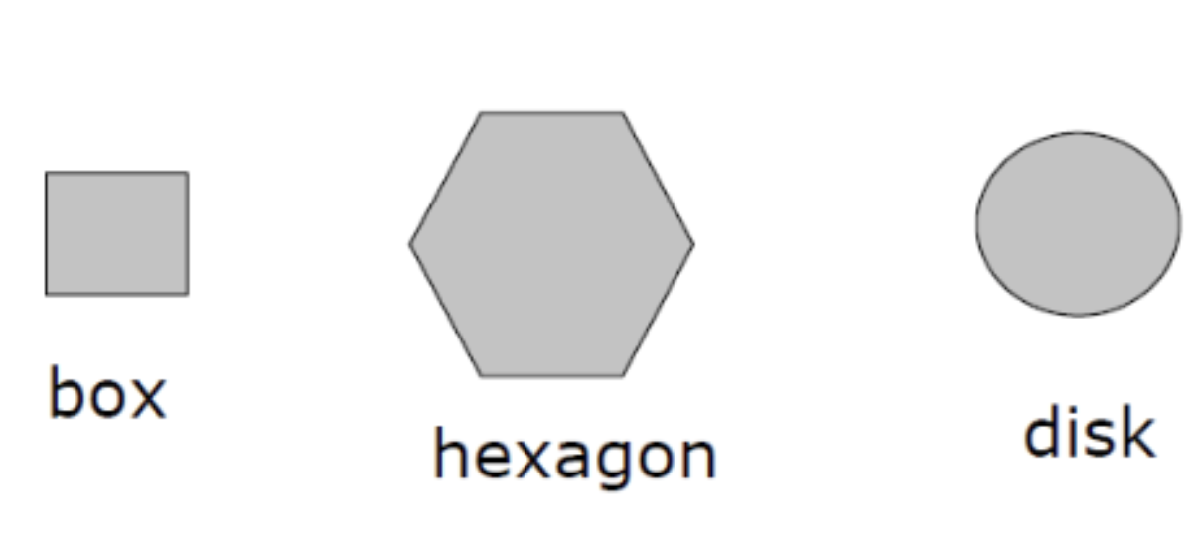

**slide 776**

**Dilation adds pixels to the contours of an object, while Erosion removes them.**

**The number of pixels added or removed depends on the shape and size of the structuring element.**

**Matlab function**

y1 = **imdilate**(x,b);

y2 = **imerode**(x,b); 

**strel** defines the Structuring Element:

[`SE =` `strel``("diamond",r)`](https://it.mathworks.com/help/releases/R2024b/images/ref/strel.html?searchHighlight=strel&s_tid=doc_srchtitle#d126e321337)

[`SE =` `strel``("disk",r)`](https://it.mathworks.com/help/releases/R2024b/images/ref/strel.html?searchHighlight=strel&s_tid=doc_srchtitle#d126e321349)

[`SE =` `strel``("disk",r,n)`](https://it.mathworks.com/help/releases/R2024b/images/ref/strel.html?searchHighlight=strel&s_tid=doc_srchtitle#d126e321366)

[`SE =` `strel``("octagon",r)`](https://it.mathworks.com/help/releases/R2024b/images/ref/strel.html?searchHighlight=strel&s_tid=doc_srchtitle#d126e321382)

[`SE =` `strel``("line",len,deg)`](https://it.mathworks.com/help/releases/R2024b/images/ref/strel.html?searchHighlight=strel&s_tid=doc_srchtitle#d126e321397)

[`SE =` `strel``("rectangle",[m n])`](https://it.mathworks.com/help/releases/R2024b/images/ref/strel.html?searchHighlight=strel&s_tid=doc_srchtitle#d126e321418)

[`SE =` `strel``("square",w)`](https://it.mathworks.com/help/releases/R2024b/images/ref/strel.html?searchHighlight=strel&s_tid=doc_srchtitle#d126e321432)

b  = **strel**(’line’,3,0);

**Exercise**:

Enhancement of a low-resolution text. One of the most simple applications of the expansion is to fill the gaps present in the characters of the text image:

Apply dilation on text2dilate.tif image with the structuring element

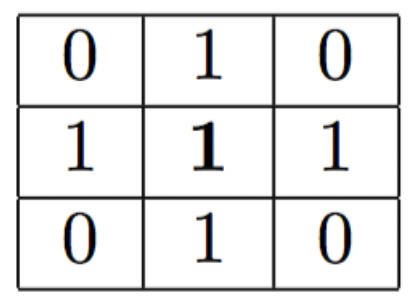

x = imread('text2dilate.tif');
figure
subplot(1,2,1)
imshow(x,[]);
b = [0 1 0; 1 1 1; 0 1 0];
y = imdilate(x,b);
subplot(1,2,2)
imshow(y,[]);

**Erosion**

Erosion  of x (m, n) by means of the structuring element b (m, n), provides the value 0 if, by sliding b (-m, -n) on x (m, n) in the neighborhood of the pixel there is at least one 0. 

**slide 789 - 790**

**exercise**:

Apply the erosion on Mask.tif image selecting the structuring element so as to generate an output image in which only the central square is present.

close all
clear
x = imread('Mask.tif');
figure; imshow(x,[]);
se=strel('square',50);
y = imerode(x,se);
figure; imshow(y,[]);
z = imdilate(y,se);
figure; imshow(z,[]);

#### **Opening and closing **

**Opening**: Erosion followed by Dilation

A ◦ B = (A ⊖ B) ⊕ B 

**Closing**: Dilation followed by erosion

A • B = (A ⊕ B) ⊖ B 

Matlab Function: **imopen** e **imclose** 

slide 795 - 796

**exercise**:

Apply the opening on Mask.tif to remove the links

close all
clear
x = imread('Mask.tif');
figure; imshow(x,[]);
se=strel('square',30);
y = imopen(x,se);
figure; imshow(y,[]);

#### Closing

Closing tends to: 

- Smooth an image 

- Fuse narrow breaks and thin gulfs

- Eliminates small holes.

**Exercise**:

**Noise Reduction**

The morphological operations may be used to construct filters conceptually similar to the spatial filters. 'fingerprint.tif' shows the section of a corrupted by noise fingerprint (white pixels on  background and black pixels on the footprint.

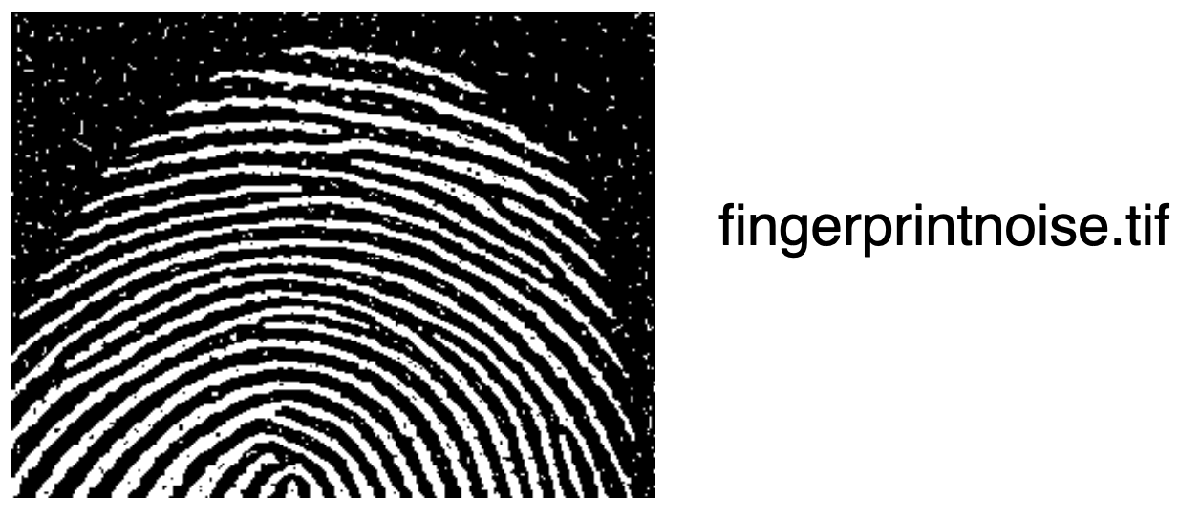

structuring element a square 3 × 3:

**Image erosion**: completely removes the noise in the background because the noise components are smaller than the structuring element, but increases the size of the noise elements on the footprint. These can be reduced or eliminated by **dilation** (opening).

new gaps between the fingerprint ridges are created. 

**Dilation**: fills the gaps created within the footprint but makes thicker the fingerprint ridges. It is therefore necessary to carry out the erosion (closing)

clear
close all
a=imread('fingerprintnoise.tif');
s=strel('square',3);
a1=imerode(a,s);
a2=imdilate(a1,s);
figure
subplot(1,2,1)
imshow(a1*255)
title('erosion');
subplot(1,2,2)
imshow(a2*255)
title('dilation');
a3=imdilate(a2,s);
a4=imerode(a3,s);
figure
subplot(1,2,1)
imshow(a3*255)
title('dilation');
subplot(1,2,2)
imshow(a4*255)
title('erosion');

clear
% close all
a=imread('fingerprintnoise.tif');
s=strel('square',3);
a1=imopen(a,s);
a2=imclose(a1,s);
figure
imshow(a2.*255)

#### **Boundary Detection **

The boundary of a binary image can be obtained through the erosion operation with a suitable structuring element and then subtracting the result from the original image:

clear
close all
x = imread('rice.tif'); 
t=graythresh(x);
x=x>t*255;
figure; imshow(x);
s = strel('square',3);
y = imerode(x,s); figure; imshow(y);
z=x-y;figure; imshow(z);

**External boundary   ** and **morphological gradient**

slide 808 - 811

clear
close all
x = imread('leaf.jpg'); 
x=rgb2gray(x);
t=graythresh(x)
x=x<t*255;
figure; 
subplot(2,2,1)
imshow(x);
title('image after thresholding')
s=strel('square',3);
xe=imerode(x,s);
x1=x-xe;
subplot(2,2,2)
imshow(x1);
title('boundary detection') 
xd=imdilate(x,s);
x2=xd-x;
subplot(2,2,3)
imshow(x2);
title('external boundary') 
x3=xd-xe;
subplot(2,2,4)
imshow(x3);
title('morphological gradient') 

**Exercise**:

**Recognize characters on a license plate using morphological image processing**.

Binarize license_plate.png image and the template images (templates.zip).

**Detect E character.**

- **Erode template**

- **Erode target by template (eroded)**

- **Dilate eroded target by template**

clear
close all
x = imread('license_plate.png'); 
x=rgb2gray(x);
figure
imshow(x)
t=graythresh(x)
% set to 255 all pixel < t
% x=x<t binary matrix with 1 if x < t
x=x<t*255;
figure; 
subplot(2,2,1)
imshow(x);
e = imread('E.png'); 
e=rgb2gray(e);
t=graythresh(e)
e=e<t*255;
subplot(2,2,2)
imshow(e);
title('template')
s=strel('square',3);
ee=imerode(e,s);
xe=imerode(x,ee);
subplot(2,2,3)
imshow(xe);
title('plate eroded by template (eroded)')
xd=imdilate(xe,e);
subplot(2,2,4)
imshow(xd);
title('dilated (plate eroded) by template (eroded)')

#### **Exercise: remove the skull from an head MRI**

**slide 839**

- **load a MRI file (t1.nii)**

- **show a layer**

- **binarize**

- **extraction of the two largest regions**

- **remove ‘bridge’ between skull and brain**

- **extraction of the largest region (the brain)**

- **fills holes to make the mask**

- **mask the original image**

[`BW2`](https://it.mathworks.com/help/releases/R2024b/images/ref/bwareafilt.html?searchHighlight=bwareafilt&s_tid=doc_srchtitle#buiu1jb-1-BW2) `=` `bwareafilt``(`[`BW`](https://it.mathworks.com/help/releases/R2024b/images/ref/bwareafilt.html?searchHighlight=bwareafilt&s_tid=doc_srchtitle#buiu1jb-1-BW)`,`[`n`](https://it.mathworks.com/help/releases/R2024b/images/ref/bwareafilt.html?searchHighlight=bwareafilt&s_tid=doc_srchtitle#buiu1jb-1-n)`)` keeps the `n` largest objects. In the event of a tie for `n`-th place, only the first `n` objects are included in `BW2`.

%  this script example open a NII file, shows an image from the file, 
%  remove the skull

clear
close all
% open NII file
% [file,path]= uigetfile('*.nii','Select a File'); 
% filename=cat(2,path,file)
% V = niftiread(filename);
V = niftiread('T1.nii');
[x,y,z]=size(V);
fprintf('number of slice: %d\n',z);
% disp('number of slide: ',z)
% extract an image
X=input('input slice number to open ')
A=V(:,:,X);
A=uint8(A);
[rows, columns] = size(A);

% Display the image.
subplot(2, 3, 1);
imshow(A, []);
axis on;
caption = sprintf('Original Grayscale Image\n%s');
title(caption);
% 

%===========================================================================================================
% Display the histogram so we can see what gray level we need to threshold it at.
subplot(2, 3, 2:3);
% For this image, there is a huge number of black pixels with gray level less than about 11,
% and that makes a huge spike at the first bin.  
imhist(A(A >= 11))
hold on


%===========================================================================================================
% Threshold the image to make a binary image.
level = graythresh(A);
L=level*255
stem(L,500)
hold off
binaryImage = imbinarize(A, level) ;


% Display the image.
subplot(2, 3, 4);
imshow(binaryImage, []);
axis on;
title('Initial Binary Image Thresholded');

%===========================================================================================================
% Extract the two largest blobs, which will either be the skull and brain,
% or the skull/brain (if they are connected) and small noise blob.
% BW2 = bwareafilt(BW,n) keeps the n largest objects. In the event of a tie for n-th place, only the first n objects are included in BW2.

binaryImage = bwareafilt(binaryImage, 2);		% Extract 2 largest blobs.
% imopen to remove bridge.
binaryImage = imopen(binaryImage, true(5));
% Now brain should be disconnected from skull.
% So extract the brain only - it's the largest blob.
binaryImage = bwareafilt(binaryImage, 1);		% Extract largest blob.
% Fill any holes in the brain.

binaryImage = imfill(binaryImage, 'holes');
% BW2 = imfill(BW1,'holes') fills holes in the input image.  A hole is
%     a set of background pixels that cannot be reached by filling in the
%     background from the edge of the image.

% Dilate mask (in case we've chopped out a little bit of brain).
binaryImage = imdilate(binaryImage, true(5));

% Display the final binary image.
subplot(2, 3, 5);
imshow(binaryImage, []);
axis on;
title('Final Binary Image without Skull');

%===========================================================================================================
% Mask out the skull from the original gray scale image.
skullFreeImage = A; % Initialize
skullFreeImage(~binaryImage) = 0; % Mask out.
% Display the image.
subplot(2, 3, 6);
imshow(skullFreeImage, []);
axis on;
title('Gray Scale Image without Skull');


#### **Grayscale Morphology     **

Morphology operations can also be applied to grayscale images 

just replace (OR, AND) with (MAX, MIN) 

**Exercize:**

**Realized the morphological gradient of “headCT.tif ” using as a structuring element Ones(3) and observe the results in the various processing stages.**

clear
close all
x = double(imread('headCT.tif'));
figure
imshow(mat2gray(x))
title('input image');
se = ones(3,3);
y = imdilate(x,se);
z = imerode(x,se);
w = y-z;
figure;
subplot(2,2,1); imshow(x,[]);
subplot(2,2,2); imshow(y,[]);
subplot(2,2,3); imshow(z,[]);
subplot(2,2,4); imshow(w,[]);

**Smoothing **

Opening suppresses bright details smaller than a specific SE and closing suppresses dark details, these operations can then be used together to achieve the morphological filters useful for smoothing and noise reduction.

Figure supernova.tif shows the Swan Nebula, (rays X).  Suppose that the central region of the image is the object of interest, and that small components that surround it is noise.

To remove this noise you can make the opening and then closing with a disk of specified radius. 

Compare the results obtained by SE : disk with radius equal to: 1, 3 and 5

**se = strel(‘disk',n);**

**find n value to suppress small components that surround central region.**

clear
close all
x = double(imread('supernova.tif'));
subplot(2,2,1)
imshow(x,[]);
se1 = strel('disk',1);
se3 = strel('disk',3);
se5 = strel('disk',5);
y = imopen(x,se1);
z = imclose(y,se1);
subplot(2,2,2)
imshow(z,[]);
title('disk1')
y = imopen(x,se3);
z = imclose(y,se3);
subplot(2,2,3)
imshow(z,[]);
title('disk3')
y = imopen(x,se5);
z = imclose(y,se5);
subplot(2,2,4)
imshow(z,[]);
title('disk5')